## This script tries to mimick the code run on the arduino for debugging purposes.

In contrast to simulate simulateCcodeForDiscreteTimeSystemOutputOmega and -Phi, we here assume phi and omega to be available, do not implement an observer and add an integrator for the error with the measured output phi to the system.

#### Load data and check for errors.

We load the continuous-time transfer function found by identification. We also read the original data for later comparisons. 

clear all;
close all;

global Ad  Bd Cd Dd Kd Ld bref % see comment in auxiliary functions

load("../step_responses/identifyTransferFunctionContinuousTimeResults.mat");
delta_t= identifyTransferFunctionContinuousTimeResults.delta_t;
uStep= identifyTransferFunctionContinuousTimeResults.uStep;
shifted_tData= identifyTransferFunctionContinuousTimeResults.shifted_tData;
shifted_yDeg= identifyTransferFunctionContinuousTimeResults.shifted_yDeg;

We convert the identified transfer function to a state space model. The exact time discretization has been carried out in a maple sheet and we load the matrices Ad, Bd that resulted there. The C and D matrix are the same for the continuous-time state space system and its discrete-time counterpart.

load('../step_responses/mapleToMatlab/Ad.txt'); % provides Ad calculated with maple
load('../step_responses/mapleToMatlab/Bd.txt'); % provides Bd calculated with maple

The same data has also been saved by 'convertToDiscreteTimeStateSpaceSys.mlx'. (The feedback matrix K and observer matrix L calculated there are ignored in this script.) We load this data and compare it to the maple results to ensure that all files are consistent.

load('../step_responses/matlabToC/matricesForOutputOmega/matricesForOutputOmega.mat');
if ~isequal(Ad, matricesForOutputOmega.Ad) || ...
        ~isequal(Bd, matricesForOutputOmega.Bd)
    error('matrices are not equal');
end
Cd= matricesForOutputOmega.Cd;
Dd= 0;
Kd= matricesForOutputOmega.Kd;
Ld= matricesForOutputOmega.Ld;
bref= matricesForOutputOmega.bref;
sysd= ss(Ad, Bd, Cd, Dd, delta_t);

Let's compare the step response of the discrete-time system to the original simulation data. 

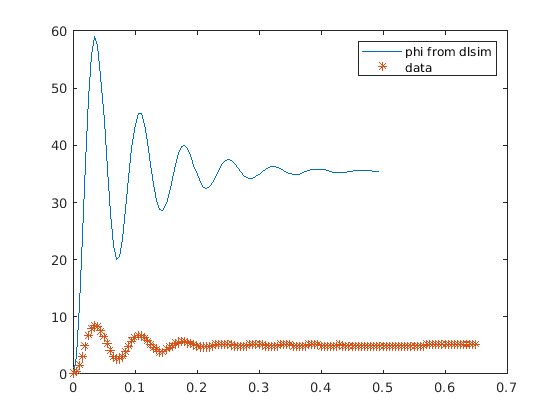

checkStep.numTimeSteps= 100;
checkStep.t= (0:checkStep.numTimeSteps-1)* delta_t;
checkStep.uStep= 35; % deg
checkStep.u= checkStep.uStep* ones(1, checkStep.numTimeSteps);
checkStep.initConds= [0 0];
[~, checkStep.x]= dlsim(sysd.A, sysd.B, sysd.C, sysd.D, checkStep.u, checkStep.initConds);
figure();
plot(checkStep.t(1,:), checkStep.x(:, 1), '-');
hold on;
plot(shifted_tData, shifted_yDeg, '*');
legend('phi from dlsim', 'data');
hold off;

#### Set up open-loop system with integrator

See the files in the Notes directory for an explanation.

sysDiscreteOpen.Abar= [Ad(1,1) Ad(1,2) 0;
    Ad(2,1) Ad(2,2) 0;
    -1 0 1]; 
sysDiscreteOpen.bbar= [Bd(1,1); 
    Bd(2,1);
    0]; 
sysDiscreteOpen.br= [0; 0; 1];
sysDiscreteOpen.cT= [1 0 0];

Simultate new open-loop system with additional integrator state and compare to measured data again.

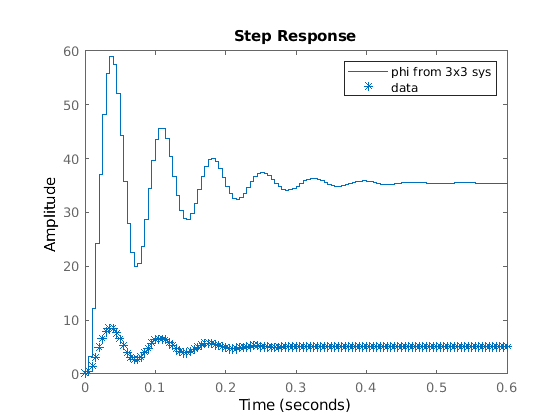

figure();
stepOpt = stepDataOptions('StepAmplitude', checkStep.uStep);
step(ss(sysDiscreteOpen.Abar, sysDiscreteOpen.bbar, sysDiscreteOpen.cT, 0, delta_t), stepOpt); 
hold on;
plot(shifted_tData, shifted_yDeg, '*');
legend('phi from 3x3 sys', 'data');
hold off;

#### Close loop for system with integrator with state feedback

Set desired poles in continuous time and convert them to discrete time.

% continuousTimePoles= [-51, -50, -53];
continuousTimePoles= [-101, -100, -102];
discreteTimePoles= continuousTimePoleToDiscrete(continuousTimePoles, delta_t); 

sysDiscreteOpen.kbarT= place(sysDiscreteOpen.Abar, sysDiscreteOpen.bbar, discreteTimePoles); 

Create closed-loop system.

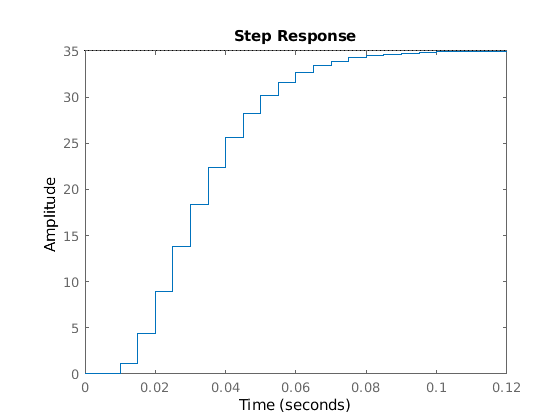

sysDiscreteClosed= ss(sysDiscreteOpen.Abar- sysDiscreteOpen.bbar* sysDiscreteOpen.kbarT, ...
    sysDiscreteOpen.br, sysDiscreteOpen.cT, 0, delta_t);
figure();
stepOpt = stepDataOptions('StepAmplitude', checkStep.uStep);
step(sysDiscreteClosed, stepOpt); 

## Mimick control with arduino

Variable x contains the simulated states. For the arduino and the real system

numSimTimeSteps= 100;
t= (0:numSimTimeSteps-1)* delta_t; % in seconds
x= zeros(2, numSimTimeSteps);

